% Clear workspace and initialize parameters
close all;
clear all;
addpath('../custom_functions')  % use correct relative path


% % System parameters
m = 0.04;
c = 1.5874;
k = 1.0197e+04;
model.R = 1;
model.L = 250 * 1e-06;
model.G = 12.3;
model.kappa = 42.5e+05;

omega1 = 2*pi*14.6;
omega2 = 2*pi*200;
xi1 = 0.03;
xi2 = 0.09;

model.Phiell = [-7.382136522799137;7.360826867549465];
model.Phid = [-0.328118182993717;-1.714004051780882];
Phiell = model.Phiell;
Phid = model.Phid;

Z=[2*xi1*omega1 0;0 2*xi2*omega2];
Omega=[omega1^2 0;0 omega2^2];

model.M = eye(2) + m*Phid*Phid';
model.C = Z + c*Phid*Phid';
model.K = Omega + k*Phid*Phid';

model.Ts = 1/1000;



## EOMs

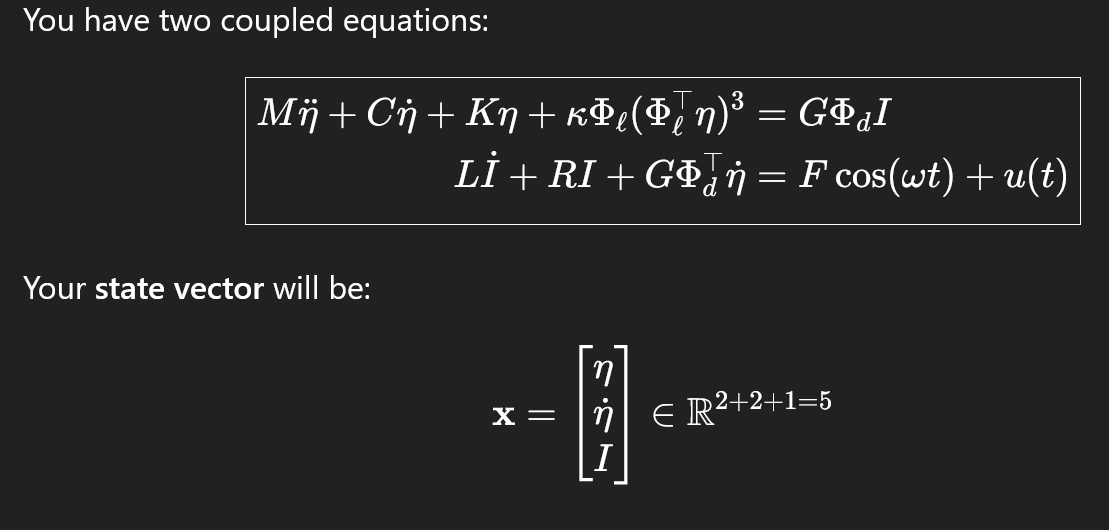

% Initial conditions: [eta0; eta_dot0; I0]
x0 = zeros(5,1);

% Define forcing
model.F = 10;
model.omega = 2*pi*37.6799;

% Control input (function of time)
model.u_fun = @(t) model.F * sin(model.omega * t);  % no control input for now
model.eta_ddot_star = @(t) 0;%-A_target * omega^2 * sin(omega * t);

% Time span
tspan = [0 0.5];

% Solve
[t, x] = ode45(@(t,x) f_beam_shaker_model(t, x, model), tspan, x0);

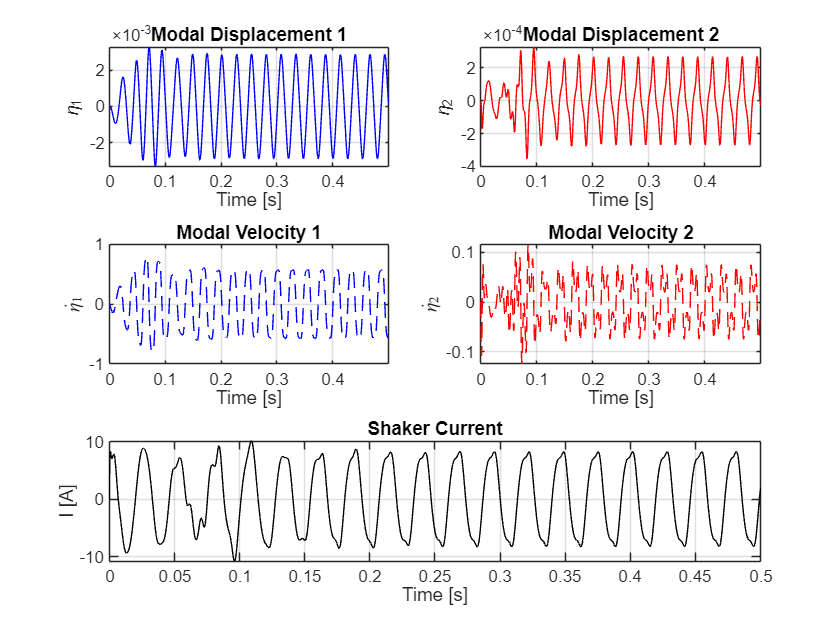

% Assuming you have run: [t, x] = ode45(...)

% Create figure and tiled layout
figure;
tiledlayout(3,2, "TileSpacing","compact");  % 3 rows, 2 columns (one empty tile)

% Modal displacement eta_1
nexttile;
plot(t, x(:,1), 'b');
xlabel('Time [s]');
ylabel('\eta_1');
title('Modal Displacement 1');
xlim([0, t(end)]);
grid on;

% Modal displacement eta_2
nexttile;
plot(t, x(:,2), 'r');
xlabel('Time [s]');
ylabel('\eta_2');
title('Modal Displacement 2');
xlim([0, t(end)]);
grid on;

% Modal velocity eta_dot_1
nexttile;
plot(t, x(:,3), 'b--');
xlabel('Time [s]');
ylabel('$\dot{\eta}_1$', 'Interpreter', 'latex');
title('Modal Velocity 1');
xlim([0, t(end)]);
grid on;

% Modal velocity eta_dot_2
nexttile;
plot(t, x(:,4), 'r--');
xlabel('Time [s]');
ylabel('$\dot{\eta}_2$', 'Interpreter', 'latex');
title('Modal Velocity 2');
xlim([0, t(end)]);
grid on;

% Shaker current I
nexttile([1 2]);  % span 2 columns
plot(t, x(:,5), 'k');
xlabel('Time [s]');
ylabel('I [A]');
title('Shaker Current');
xlim([0, t(end)]);
grid on;

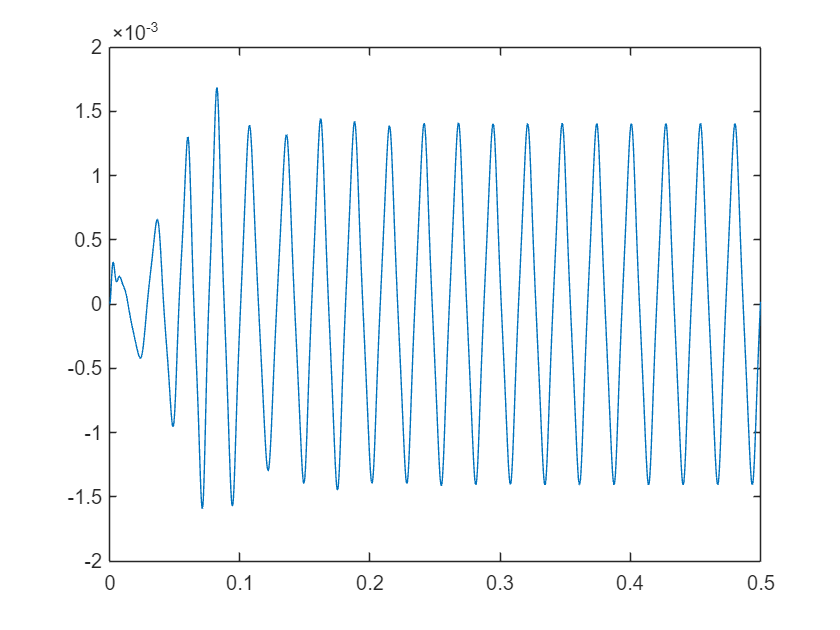

eta = x(:, 1:2);             % Extract modal displacements
w_d = eta*Phid;           % Physical displacement at position x
figure;
plot(t, w_d)